# HW1_1_3

## Convolution

close all;
clear;
clc;

To convolve two signal (use as filter in this project), output would be extended so show the output one in true form & another use "same" for remove the extended part.

Then ploting them use plot & stem function.

t   = (0: 0.01: 2);
Amp = 5;
Fs  = 1;

M1  = 0;
M2  = 20;

Func        = Amp*sin(t * Fs *2*pi);
movingAvg   = 1/(M2-M1+1) * ones(1, (M2-M1+1));

NoisyFunc   = Func + rand(1, length(Func))-0.5;

t_prime     = (0: 0.01: 2+(M2-M1)*0.01);
ConvOut     = conv(NoisyFunc, movingAvg);
ConvOut_same= conv(NoisyFunc, movingAvg, 'same');

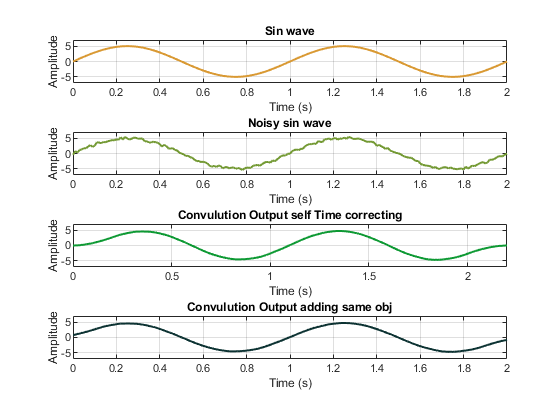

figure('Name', 'Moving Max Filtering')
subplot(4, 1, 1)
plot(t, Func, 'LineWidth', 1.5, 'Color', [0.85, 0.6, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave');
grid on;
subplot(4, 1, 2)
plot(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.45, 0.6, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy sin wave');
grid on;
subplot(4, 1, 3)
plot(t_prime, ConvOut, 'LineWidth', 1.5, 'Color', [0.05, 0.6, 0.2]);
xlim([0 t_prime(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output self Time correcting');
grid on;
subplot(4, 1, 4)
plot(t, ConvOut_same, 'LineWidth', 1.5, 'Color', [0.05, 0.2, 0.2]);
xlim([0 t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output adding same obj');
grid on;

M1  = -10;
M2  = 10;

Func        = Amp*sin(t * Fs *2*pi);
movingAvg   = 1/(M2-M1+1) * ones(1, (M2-M1+1));

NoisyFunc   = Func + rand(1, length(Func))-0.5;

t           = (M1*0.01: 0.01: 2);
Func        = [zeros(1, abs(M1)), Func];
NoisyFunc   = [zeros(1, abs(M1)), NoisyFunc];

t_prime     = (0: 0.01: 2+(M2-M1)*0.01);
ConvOut     = conv(NoisyFunc, movingAvg);
ConvOut     = ConvOut(1+M2-M1: end);
ConvOut_same= conv(NoisyFunc, movingAvg, 'same');

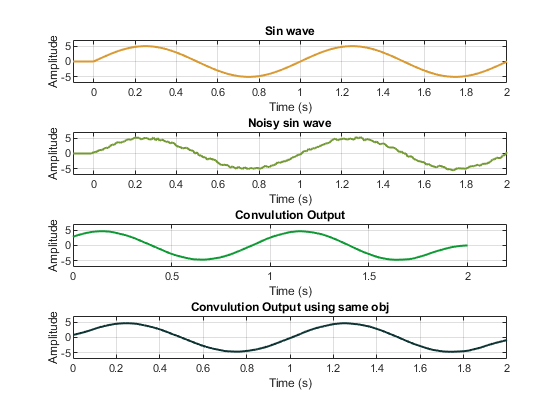

figure('Name', 'Moving Max Filtering')
subplot(4, 1, 1)
plot(t, Func, 'LineWidth', 1.5, 'Color', [0.85, 0.6, 0.2]);
xlim([t(1) t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave');
grid on;
subplot(4, 1, 2)
plot(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.45, 0.6, 0.2]);
xlim([t(1) t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy sin wave');
grid on;
subplot(4, 1, 3)
plot(t, ConvOut, 'LineWidth', 1.5, 'Color', [0.05, 0.6, 0.2]);
xlim([0 t_prime(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output');
grid on;
subplot(4, 1, 4)
plot(t, ConvOut_same, 'LineWidth', 1.5, 'Color', [0.05, 0.2, 0.2]);
xlim([0 t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output using same obj');
grid on;